## Gurobi: general Pareto front and time benchmarking

### Uniform weights, step 0.1, alpha=25 (penalty factor)

% Span for uniform weights
span = 0.01:0.1:0.99;

% Placeholders for costs and runtimes
cost_gurobi = zeros(length(span), 2);
runtime_gurobi = zeros(1, length(span));
cost_sedumi = zeros(length(span), 2);
runtime_sedumi = zeros(1, length(span));
objective_gurobi = zeros(1, length(span));
loss = zeros(1, length(span));

% Penalty
alpha = 25;

% Load the network into the workspace
network = network_init(4, 10);

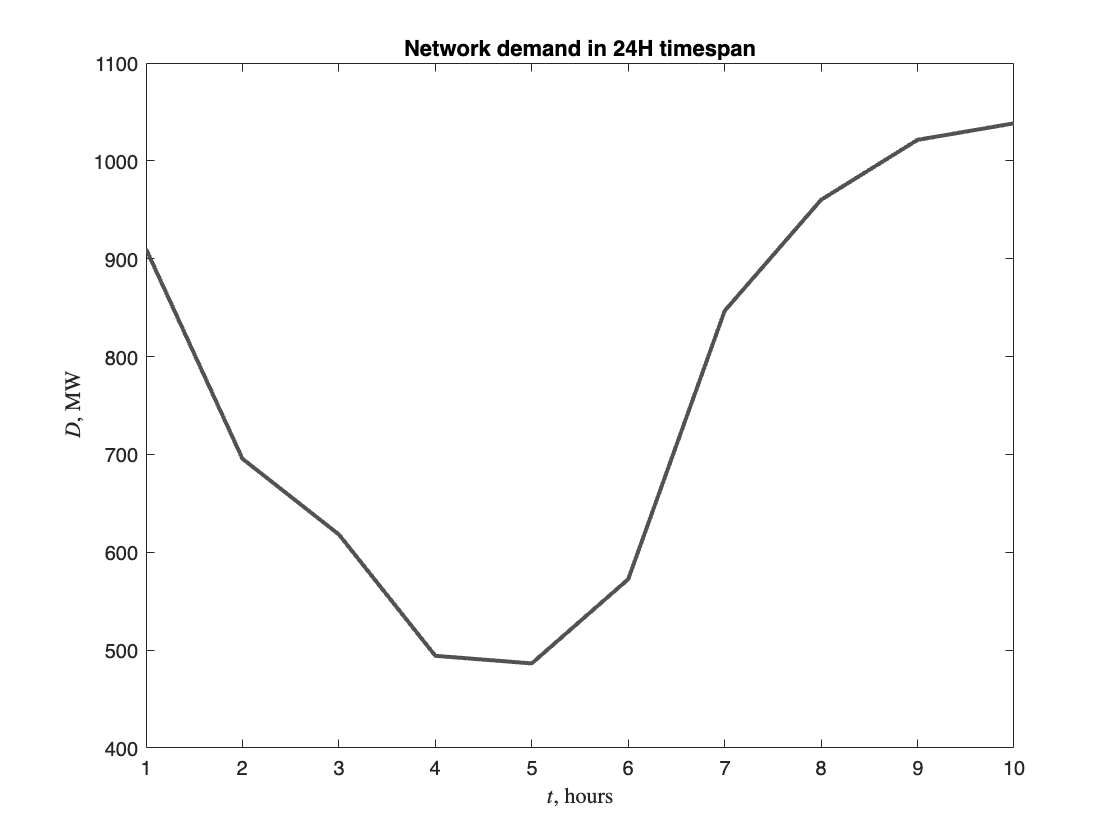

demand_color = [83 81 84]/255;

figure()
plot(1:1:10, network.demand, LineWidth=2, Color=demand_color);
title('Network demand in 24H timespan')
xlabel('$t$, hours', 'Interpreter','latex');
ylabel('$D$, MW', 'Interpreter','latex');

% Run computations for one network, different weights

for i = 1:length(span)
    w2 = span(i);
    w1 = 1 - w2;
    fprintf('Iteration %d: w1=%d, w2=%d\n', i, w1, w2);
    network.c = w1 * (network.c1 + alpha * network.cpen) + w2 * network.c2;
    network.Q_biobj = network.Q * w1;
    result_gurobi = solve_gurobi(network);
    [cost_gurobi(i, 1), cost_gurobi(i, 2)] = objective_values(network, alpha, result_gurobi.x);
    runtime_gurobi(i) = result_gurobi.runtime;
    [result_sedumi, runtime_sedumi(i)] = solve_sedumi(network);
    [cost_sedumi(i, 1), cost_sedumi(i, 2)] = objective_values(network, alpha, result_sedumi);
    objective_gurobi(i) = result_gurobi.objval;
    loss(i) = sum(abs(result_gurobi.x - result_sedumi));
end

Iteration 1: w1=9.900000e-01, w2=1.000000e-02


Set parameter Username
Set parameter Threads to value 1
Academic license - for non-commercial use only - expires 2025-04-13
Gurobi Optimizer version 11.0.1 build v11.0.1rc0 (mac64[arm] - Darwin 23.5.0 23F79)

CPU model: Apple M1
Thread count: 8 physical cores, 8 logical processors, using up to 1 threads

Optimize a model with 536 rows, 200 columns and 956 nonzeros
Model fingerprint: 0x4dc10353
Model has 40 quadratic objective terms
Variable types: 80 continuous, 120 integer (120 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 1e+04]
  QObjective range [6e-04, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 1e+03]
Found heuristic solution: objective 9.900002e+11
Presolve removed 470 rows and 96 columns
Presolve time: 0.01s
Presolved: 66 rows, 104 columns, 199 nonzeros
Presolved model has 36 quadratic objective terms
Found heuristic solution: objective 182812.62820
Variable types: 50 continuous, 54 integer (54 binary)
Found

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 20301, order n = 740, dim = 40940, blocks = 3
nnz(A) = 21258 + 0, nnz(ADA) = 412130601, nnz(L) = 206075451
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            2.19E-04 0.000
  1 :   4.14E+06 1.59E-04 0.000 

Iteration 2: w1=8.900000e-01, w2=1.100000e-01


Set parameter Username
Set parameter Threads to value 1
Academic license - for non-commercial use only - expires 2025-04-13
Gurobi Optimizer version 11.0.1 build v11.0.1rc0 (mac64[arm] - Darwin 23.5.0 23F79)

CPU model: Apple M1
Thread count: 8 physical cores, 8 logical processors, using up to 1 threads

Optimize a model with 78 rows, 28 columns and 118 nonzeros
Model fingerprint: 0xd5772a74
Model has 4 quadratic objective terms
Variable types: 12 continuous, 16 integer (16 binary)
Coefficient statistics:
  Matrix range     [1e+00, 6e+01]
  Objective range  [2e-02, 6e+02]
  QObjective range [3e-03, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 9e+01]
Found heuristic solution: objective 1.780000e+11
Presolve removed 76 rows and 24 columns
Presolve time: 0.00s
Presolved: 2 rows, 4 columns, 5 nonzeros
Presolved model has 2 quadratic objective terms
Found heuristic solution: objective 6483.0963387
Variable types: 3 continuous, 1 integer (1 binary)

Root relaxation: ob

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 435, order n = 110, dim = 922, blocks = 3
nnz(A) = 554 + 0, nnz(ADA) = 189225, nnz(L) = 94830
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.25E-03 0.000
  1 :  -9.80E+03 1.86E-03 0.000 0.4382 0.9000 0.9000   1.18  1  1  8.5E+01
  2 :  -1.12E+04 6.43E-04 0.000 0.3448 0.9000 0.9000   1.41  1  1  2.5E+01
  3 :  -1.02E+04 2.73E-04 0.000 0.4242 0.9000 0.9000   1.13  1  1  1.0E+01
  4 :  -8.99E+03 1.33E-04 0.000 0.4895 0.9000 0.9000   0.93  1  1  4.9E+00
  5 :  -8.19E+03 6.76E-05 0.000 0.5065 0.9000 0.9000   0.70  1  1  2.7E+00
  6 :  -7.47E+03 4.00E-05 0.000 0.5924 0.9000 0.9000   0.86  1  1  1.5E+00
  7 :  -7.23E+03 2.07E-05 0.000 0.5162 0.9000 0.9000   0.53  1  1  9.3E-01
  8 :  -6.55E+03 9.62E-06 0.000 0.4657 0.9000 0.9000   1.10  1  1  3.5E-01
  9 :  -6.21E+03 3.79E-06 0.000 0.3935 0.9000 0.9000   0.88  1  1  1.5E-01
 10 :

Iteration 3: w1=7.900000e-01, w2=2.100000e-01


Set parameter Username
Set parameter Threads to value 1
Academic license - for non-commercial use only - expires 2025-04-13
Gurobi Optimizer version 11.0.1 build v11.0.1rc0 (mac64[arm] - Darwin 23.5.0 23F79)

CPU model: Apple M1
Thread count: 8 physical cores, 8 logical processors, using up to 1 threads

Optimize a model with 78 rows, 28 columns and 118 nonzeros
Model fingerprint: 0x04da03a5
Model has 4 quadratic objective terms
Variable types: 12 continuous, 16 integer (16 binary)
Coefficient statistics:
  Matrix range     [1e+00, 6e+01]
  Objective range  [2e-02, 5e+02]
  QObjective range [3e-03, 7e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 9e+01]
Found heuristic solution: objective 1.580000e+11
Presolve removed 76 rows and 24 columns
Presolve time: 0.00s
Presolved: 2 rows, 4 columns, 5 nonzeros
Presolved model has 2 quadratic objective terms
Found heuristic solution: objective 5767.2938051
Variable types: 3 continuous, 1 integer (1 binary)

Root relaxation: ob

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 435, order n = 110, dim = 922, blocks = 3
nnz(A) = 554 + 0, nnz(ADA) = 189225, nnz(L) = 94830
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.79E-03 0.000
  1 :  -8.71E+03 2.10E-03 0.000 0.4382 0.9000 0.9000   1.18  1  1  8.5E+01
  2 :  -9.98E+03 7.24E-04 0.000 0.3448 0.9000 0.9000   1.41  1  1  2.5E+01
  3 :  -9.03E+03 3.07E-04 0.000 0.4242 0.9000 0.9000   1.13  1  1  1.0E+01
  4 :  -7.99E+03 1.50E-04 0.000 0.4895 0.9000 0.9000   0.93  1  1  4.9E+00
  5 :  -7.29E+03 7.61E-05 0.000 0.5065 0.9000 0.9000   0.70  1  1  2.7E+00
  6 :  -6.64E+03 4.51E-05 0.000 0.5924 0.9000 0.9000   0.86  1  1  1.5E+00
  7 :  -6.44E+03 2.33E-05 0.000 0.5162 0.9000 0.9000   0.53  1  1  9.3E-01
  8 :  -5.83E+03 1.08E-05 0.000 0.4657 0.9000 0.9000   1.10  1  1  3.5E-01
  9 :  -5.53E+03 4.27E-06 0.000 0.3938 0.9000 0.9000   0.88  1  1  1.5E-01
 10 :

Iteration 4: w1=6.900000e-01, w2=3.100000e-01


Set parameter Username
Set parameter Threads to value 1
Academic license - for non-commercial use only - expires 2025-04-13
Gurobi Optimizer version 11.0.1 build v11.0.1rc0 (mac64[arm] - Darwin 23.5.0 23F79)

CPU model: Apple M1
Thread count: 8 physical cores, 8 logical processors, using up to 1 threads

Optimize a model with 78 rows, 28 columns and 118 nonzeros
Model fingerprint: 0x62bcbf51
Model has 4 quadratic objective terms
Variable types: 12 continuous, 16 integer (16 binary)
Coefficient statistics:
  Matrix range     [1e+00, 6e+01]
  Objective range  [1e-02, 5e+02]
  QObjective range [2e-03, 6e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 9e+01]
Found heuristic solution: objective 1.380000e+11
Presolve removed 76 rows and 24 columns
Presolve time: 0.00s
Presolved: 2 rows, 4 columns, 5 nonzeros
Presolved model has 2 quadratic objective terms
Found heuristic solution: objective 5051.4912714
Variable types: 3 continuous, 1 integer (1 binary)

Root relaxation: ob

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 435, order n = 110, dim = 922, blocks = 3
nnz(A) = 554 + 0, nnz(ADA) = 189225, nnz(L) = 94830
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            5.48E-03 0.000
  1 :  -7.62E+03 2.40E-03 0.000 0.4382 0.9000 0.9000   1.18  1  1  8.5E+01
  2 :  -8.73E+03 8.28E-04 0.000 0.3448 0.9000 0.9000   1.41  1  1  2.5E+01
  3 :  -7.91E+03 3.51E-04 0.000 0.4242 0.9000 0.9000   1.13  1  1  1.0E+01
  4 :  -7.00E+03 1.72E-04 0.000 0.4895 0.9000 0.9000   0.93  1  1  4.9E+00
  5 :  -6.38E+03 8.71E-05 0.000 0.5065 0.9000 0.9000   0.70  1  1  2.7E+00
  6 :  -5.82E+03 5.16E-05 0.000 0.5923 0.9000 0.9000   0.86  1  1  1.5E+00
  7 :  -5.64E+03 2.66E-05 0.000 0.5162 0.9000 0.9000   0.53  1  1  9.3E-01
  8 :  -5.11E+03 1.24E-05 0.000 0.4656 0.9000 0.9000   1.10  1  1  3.5E-01
  9 :  -4.85E+03 4.89E-06 0.000 0.3941 0.9000 0.9000   0.88  1  1  1.5E-01
 10 :

Iteration 5: w1=5.900000e-01, w2=4.100000e-01


Set parameter Username
Set parameter Threads to value 1
Academic license - for non-commercial use only - expires 2025-04-13
Gurobi Optimizer version 11.0.1 build v11.0.1rc0 (mac64[arm] - Darwin 23.5.0 23F79)

CPU model: Apple M1
Thread count: 8 physical cores, 8 logical processors, using up to 1 threads

Optimize a model with 78 rows, 28 columns and 118 nonzeros
Model fingerprint: 0x410c901b
Model has 4 quadratic objective terms
Variable types: 12 continuous, 16 integer (16 binary)
Coefficient statistics:
  Matrix range     [1e+00, 6e+01]
  Objective range  [1e-02, 4e+02]
  QObjective range [2e-03, 5e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 9e+01]
Found heuristic solution: objective 1.180000e+11
Presolve removed 76 rows and 24 columns
Presolve time: 0.00s
Presolved: 2 rows, 4 columns, 5 nonzeros
Presolved model has 2 quadratic objective terms
Found heuristic solution: objective 4335.6887378
Variable types: 3 continuous, 1 integer (1 binary)

Root relaxation: ob

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 435, order n = 110, dim = 922, blocks = 3
nnz(A) = 554 + 0, nnz(ADA) = 189225, nnz(L) = 94830
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            6.41E-03 0.000
  1 :  -6.52E+03 2.81E-03 0.000 0.4382 0.9000 0.9000   1.18  1  1  8.5E+01
  2 :  -7.48E+03 9.69E-04 0.000 0.3448 0.9000 0.9000   1.41  1  1  2.5E+01
  3 :  -6.78E+03 4.11E-04 0.000 0.4241 0.9000 0.9000   1.13  1  1  1.0E+01
  4 :  -6.00E+03 2.01E-04 0.000 0.4894 0.9000 0.9000   0.93  1  1  4.9E+00
  5 :  -5.48E+03 1.02E-04 0.000 0.5065 0.9000 0.9000   0.70  1  1  2.7E+00
  6 :  -4.99E+03 6.03E-05 0.000 0.5923 0.9000 0.9000   0.86  1  1  1.5E+00
  7 :  -4.84E+03 3.11E-05 0.000 0.5162 0.9000 0.9000   0.53  1  1  9.3E-01
  8 :  -4.39E+03 1.45E-05 0.000 0.4655 0.9000 0.9000   1.10  1  1  3.5E-01
  9 :  -4.16E+03 5.72E-06 0.000 0.3946 0.9000 0.9000   0.88  1  1  1.5E-01
 10 :

Iteration 6: w1=4.900000e-01, w2=5.100000e-01


Set parameter Username
Set parameter Threads to value 1
Academic license - for non-commercial use only - expires 2025-04-13
Gurobi Optimizer version 11.0.1 build v11.0.1rc0 (mac64[arm] - Darwin 23.5.0 23F79)

CPU model: Apple M1
Thread count: 8 physical cores, 8 logical processors, using up to 1 threads

Optimize a model with 78 rows, 28 columns and 118 nonzeros
Model fingerprint: 0xea3fc56d
Model has 4 quadratic objective terms
Variable types: 12 continuous, 16 integer (16 binary)
Coefficient statistics:
  Matrix range     [1e+00, 6e+01]
  Objective range  [1e-02, 3e+02]
  QObjective range [2e-03, 4e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 9e+01]
Found heuristic solution: objective 9.800000e+10
Presolve removed 76 rows and 24 columns
Presolve time: 0.00s
Presolved: 2 rows, 4 columns, 5 nonzeros
Presolved model has 2 quadratic objective terms
Found heuristic solution: objective 3619.8862041
Variable types: 3 continuous, 1 integer (1 binary)

Root relaxation: ob

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 435, order n = 110, dim = 922, blocks = 3
nnz(A) = 554 + 0, nnz(ADA) = 189225, nnz(L) = 94830
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            7.71E-03 0.000
  1 :  -5.43E+03 3.38E-03 0.000 0.4383 0.9000 0.9000   1.18  1  1  8.5E+01
  2 :  -6.23E+03 1.17E-03 0.000 0.3448 0.9000 0.9000   1.41  1  1  2.5E+01
  3 :  -5.65E+03 4.94E-04 0.000 0.4241 0.9000 0.9000   1.13  1  1  1.0E+01
  4 :  -5.01E+03 2.42E-04 0.000 0.4894 0.9000 0.9000   0.93  1  1  4.9E+00
  5 :  -4.57E+03 1.23E-04 0.000 0.5065 0.9000 0.9000   0.70  1  1  2.7E+00
  6 :  -4.17E+03 7.26E-05 0.000 0.5922 0.9000 0.9000   0.86  1  1  1.5E+00
  7 :  -4.04E+03 3.75E-05 0.000 0.5162 0.9000 0.9000   0.53  1  1  9.3E-01
  8 :  -3.66E+03 1.74E-05 0.000 0.4654 0.9000 0.9000   1.10  1  1  3.5E-01
  9 :  -3.48E+03 6.89E-06 0.000 0.3952 0.9000 0.9000   0.88  1  1  1.5E-01
 10 :

Iteration 7: w1=3.900000e-01, w2=6.100000e-01


Set parameter Username
Set parameter Threads to value 1
Academic license - for non-commercial use only - expires 2025-04-13
Gurobi Optimizer version 11.0.1 build v11.0.1rc0 (mac64[arm] - Darwin 23.5.0 23F79)

CPU model: Apple M1
Thread count: 8 physical cores, 8 logical processors, using up to 1 threads

Optimize a model with 78 rows, 28 columns and 118 nonzeros
Model fingerprint: 0x9480ab18
Model has 4 quadratic objective terms
Variable types: 12 continuous, 16 integer (16 binary)
Coefficient statistics:
  Matrix range     [1e+00, 6e+01]
  Objective range  [8e-03, 3e+02]
  QObjective range [1e-03, 3e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 9e+01]
Found heuristic solution: objective 7.800000e+10
Presolve removed 76 rows and 24 columns
Presolve time: 0.00s
Presolved: 2 rows, 4 columns, 5 nonzeros
Presolved model has 2 quadratic objective terms
Found heuristic solution: objective 2904.0836705
Variable types: 3 continuous, 1 integer (1 binary)

Root relaxation: ob

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 435, order n = 110, dim = 922, blocks = 3
nnz(A) = 554 + 0, nnz(ADA) = 189225, nnz(L) = 94830
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            9.68E-03 0.000
  1 :  -4.34E+03 4.24E-03 0.000 0.4383 0.9000 0.9000   1.18  1  1  8.5E+01
  2 :  -4.99E+03 1.46E-03 0.000 0.3448 0.9000 0.9000   1.41  1  1  2.5E+01
  3 :  -4.52E+03 6.21E-04 0.000 0.4241 0.9000 0.9000   1.13  1  1  1.0E+01
  4 :  -4.01E+03 3.04E-04 0.000 0.4894 0.9000 0.9000   0.93  1  1  4.9E+00
  5 :  -3.66E+03 1.54E-04 0.000 0.5064 0.9000 0.9000   0.70  1  1  2.7E+00
  6 :  -3.34E+03 9.11E-05 0.000 0.5921 0.9000 0.9000   0.86  1  1  1.5E+00
  7 :  -3.24E+03 4.70E-05 0.000 0.5163 0.9000 0.9000   0.53  1  1  9.3E-01
  8 :  -2.94E+03 2.19E-05 0.000 0.4653 0.9000 0.9000   1.10  1  1  3.5E-01
  9 :  -2.79E+03 8.67E-06 0.000 0.3961 0.9000 0.9000   0.88  1  1  1.5E-01
 10 :

Iteration 8: w1=2.900000e-01, w2=7.100000e-01


Set parameter Username
Set parameter Threads to value 1
Academic license - for non-commercial use only - expires 2025-04-13
Gurobi Optimizer version 11.0.1 build v11.0.1rc0 (mac64[arm] - Darwin 23.5.0 23F79)

CPU model: Apple M1
Thread count: 8 physical cores, 8 logical processors, using up to 1 threads

Optimize a model with 78 rows, 28 columns and 118 nonzeros
Model fingerprint: 0xe15663e6
Model has 4 quadratic objective terms
Variable types: 12 continuous, 16 integer (16 binary)
Coefficient statistics:
  Matrix range     [1e+00, 6e+01]
  Objective range  [6e-03, 2e+02]
  QObjective range [1e-03, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 9e+01]
Found heuristic solution: objective 5.800000e+10
Presolve removed 76 rows and 24 columns
Presolve time: 0.00s
Presolved: 2 rows, 4 columns, 5 nonzeros
Presolved model has 2 quadratic objective terms
Found heuristic solution: objective 2188.2811368
Variable types: 3 continuous, 1 integer (1 binary)

Root relaxation: ob

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 435, order n = 110, dim = 922, blocks = 3
nnz(A) = 554 + 0, nnz(ADA) = 189225, nnz(L) = 94830
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.30E-02 0.000
  1 :  -3.25E+03 5.70E-03 0.000 0.4383 0.9000 0.9000   1.18  1  1  8.5E+01
  2 :  -3.74E+03 1.97E-03 0.000 0.3448 0.9000 0.9000   1.41  1  1  2.5E+01
  3 :  -3.40E+03 8.33E-04 0.000 0.4240 0.9000 0.9000   1.13  1  1  1.0E+01
  4 :  -3.02E+03 4.08E-04 0.000 0.4893 0.9000 0.9000   0.92  1  1  4.9E+00
  5 :  -2.76E+03 2.07E-04 0.000 0.5064 0.9000 0.9000   0.70  1  1  2.7E+00
  6 :  -2.52E+03 1.22E-04 0.000 0.5919 0.9000 0.9000   0.86  1  1  1.5E+00
  7 :  -2.45E+03 6.31E-05 0.000 0.5163 0.9000 0.9000   0.53  1  1  9.3E-01
  8 :  -2.22E+03 2.94E-05 0.000 0.4651 0.9000 0.9000   1.10  1  1  3.5E-01
  9 :  -2.11E+03 1.17E-05 0.000 0.3976 0.9000 0.9000   0.88  1  1  1.5E-01
 10 :

Iteration 9: w1=1.900000e-01, w2=8.100000e-01


Set parameter Username
Set parameter Threads to value 1
Academic license - for non-commercial use only - expires 2025-04-13
Gurobi Optimizer version 11.0.1 build v11.0.1rc0 (mac64[arm] - Darwin 23.5.0 23F79)

CPU model: Apple M1
Thread count: 8 physical cores, 8 logical processors, using up to 1 threads

Optimize a model with 78 rows, 28 columns and 118 nonzeros
Model fingerprint: 0x93f9350d
Model has 4 quadratic objective terms
Variable types: 12 continuous, 16 integer (16 binary)
Coefficient statistics:
  Matrix range     [1e+00, 6e+01]
  Objective range  [4e-03, 1e+02]
  QObjective range [7e-04, 2e-03]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 9e+01]
Found heuristic solution: objective 3.800000e+10
Presolve removed 76 rows and 24 columns
Presolve time: 0.00s
Presolved: 2 rows, 4 columns, 5 nonzeros
Presolved model has 2 quadratic objective terms
Found heuristic solution: objective 1472.4786031
Variable types: 3 continuous, 1 integer (1 binary)

Root relaxation: ob

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 435, order n = 110, dim = 922, blocks = 3
nnz(A) = 554 + 0, nnz(ADA) = 189225, nnz(L) = 94830
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            1.98E-02 0.000
  1 :  -2.16E+03 8.68E-03 0.000 0.4384 0.9000 0.9000   1.18  1  1  8.5E+01
  2 :  -2.49E+03 2.99E-03 0.000 0.3448 0.9000 0.9000   1.42  1  1  2.5E+01
  3 :  -2.27E+03 1.27E-03 0.000 0.4238 0.9000 0.9000   1.13  1  1  1.0E+01
  4 :  -2.02E+03 6.20E-04 0.000 0.4891 0.9000 0.9000   0.92  1  1  4.9E+00
  5 :  -1.85E+03 3.14E-04 0.000 0.5063 0.9000 0.9000   0.70  1  1  2.7E+00
  6 :  -1.70E+03 1.86E-04 0.000 0.5916 0.9000 0.9000   0.86  1  1  1.5E+00
  7 :  -1.65E+03 9.60E-05 0.000 0.5164 0.9000 0.9000   0.53  1  1  9.2E-01
  8 :  -1.50E+03 4.46E-05 0.000 0.4648 0.9000 0.9000   1.10  1  1  3.5E-01
  9 :  -1.42E+03 1.79E-05 0.000 0.4006 0.9000 0.9000   0.88  1  1  1.5E-01
 10 :

Iteration 10: w1=9.000000e-02, w2=9.100000e-01


Set parameter Username
Set parameter Threads to value 1
Academic license - for non-commercial use only - expires 2025-04-13
Gurobi Optimizer version 11.0.1 build v11.0.1rc0 (mac64[arm] - Darwin 23.5.0 23F79)

CPU model: Apple M1
Thread count: 8 physical cores, 8 logical processors, using up to 1 threads

Optimize a model with 78 rows, 28 columns and 118 nonzeros
Model fingerprint: 0x3ecc4895
Model has 4 quadratic objective terms
Variable types: 12 continuous, 16 integer (16 binary)
Coefficient statistics:
  Matrix range     [1e+00, 6e+01]
  Objective range  [2e-03, 6e+01]
  QObjective range [3e-04, 7e-04]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 9e+01]
Found heuristic solution: objective 1.800000e+10
Presolve removed 76 rows and 24 columns
Presolve time: 0.00s
Presolved: 2 rows, 4 columns, 5 nonzeros
Presolved model has 2 quadratic objective terms
Found heuristic solution: objective 756.6760695
Variable types: 3 continuous, 1 integer (1 binary)

Root relaxation: obj

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 435, order n = 110, dim = 922, blocks = 3
nnz(A) = 554 + 0, nnz(ADA) = 189225, nnz(L) = 94830
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            4.14E-02 0.000
  1 :  -1.07E+03 1.82E-02 0.000 0.4388 0.9000 0.9000   1.19  1  1  8.5E+01
  2 :  -1.24E+03 6.27E-03 0.000 0.3447 0.9000 0.9000   1.42  1  1  2.4E+01
  3 :  -1.14E+03 2.65E-03 0.000 0.4234 0.9000 0.9000   1.12  1  1  1.0E+01
  4 :  -1.02E+03 1.30E-03 0.000 0.4885 0.9000 0.9000   0.92  1  1  4.9E+00
  5 :  -9.44E+02 6.56E-04 0.000 0.5060 0.9000 0.9000   0.70  1  1  2.7E+00
  6 :  -8.70E+02 3.87E-04 0.000 0.5904 0.9000 0.9000   0.86  1  1  1.5E+00
  7 :  -8.47E+02 2.00E-04 0.000 0.5166 0.9000 0.9000   0.53  1  1  9.2E-01
  8 :  -7.74E+02 9.29E-05 0.000 0.4646 0.9000 0.9000   1.09  1  1  3.5E-01
  9 :  -7.37E+02 3.80E-05 0.000 0.4089 0.9000 0.9000   0.88  1  1  1.5E-01
 10 :

gurobi_color = [146 36 40] / 255;
sedumi_color = [57 106 177] / 255;

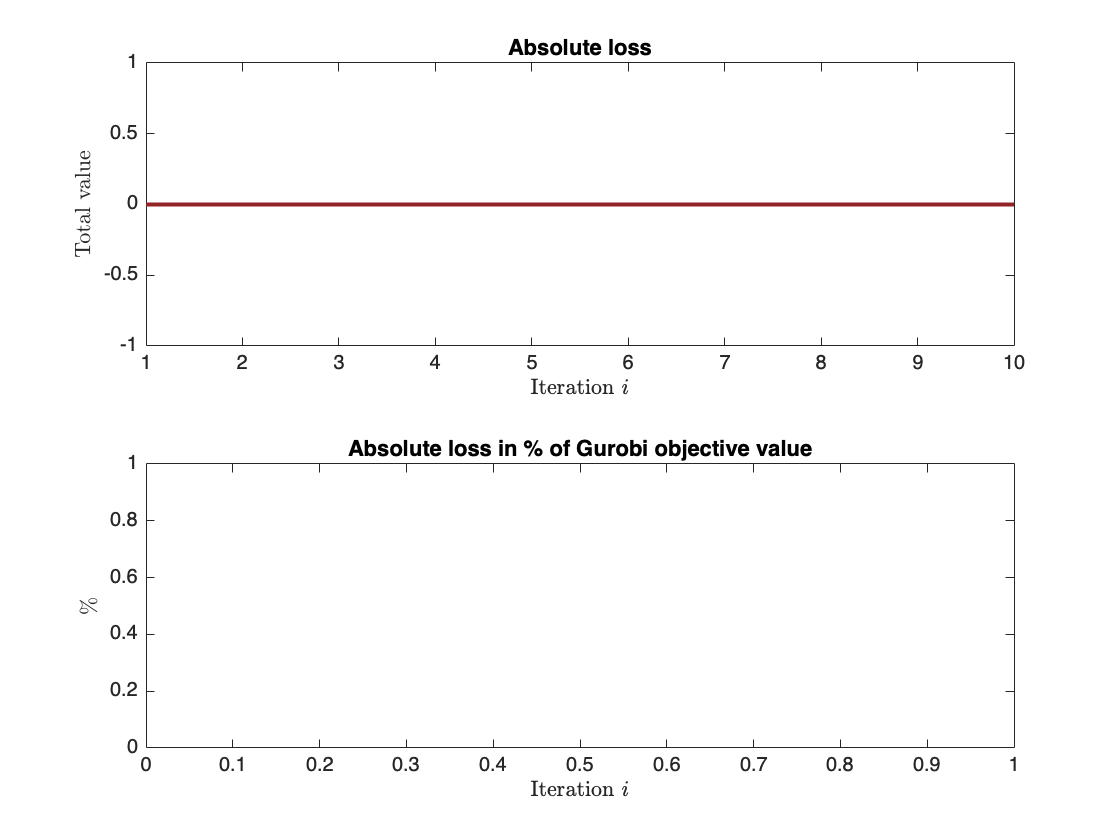

% MSE plot

% Tiles for plot
tiledlayout(2,1);
% Move to the next plot tile
nexttile
plot(1:1:length(runtime_gurobi), loss, 'Color', gurobi_color, LineWidth=2); hold on
%yline(mean(loss),'--','Average loss', Color=gurobi_color); hold off
title('Absolute loss');
xlabel('Iteration $i$', 'Interpreter','latex');
ylabel('Total value', 'Interpreter','latex');
nexttile
plot(1:1:length(runtime_sedumi), loss./objective_gurobi, 'Color', sedumi_color, LineWidth=2); hold on
yline(mean(loss./objective_gurobi),'--','Average %', Color=sedumi_color); hold off
title('Absolute loss in % of Gurobi objective value');
xlabel('Iteration $i$', 'Interpreter','latex');
ylabel('\%', 'Interpreter', 'latex');

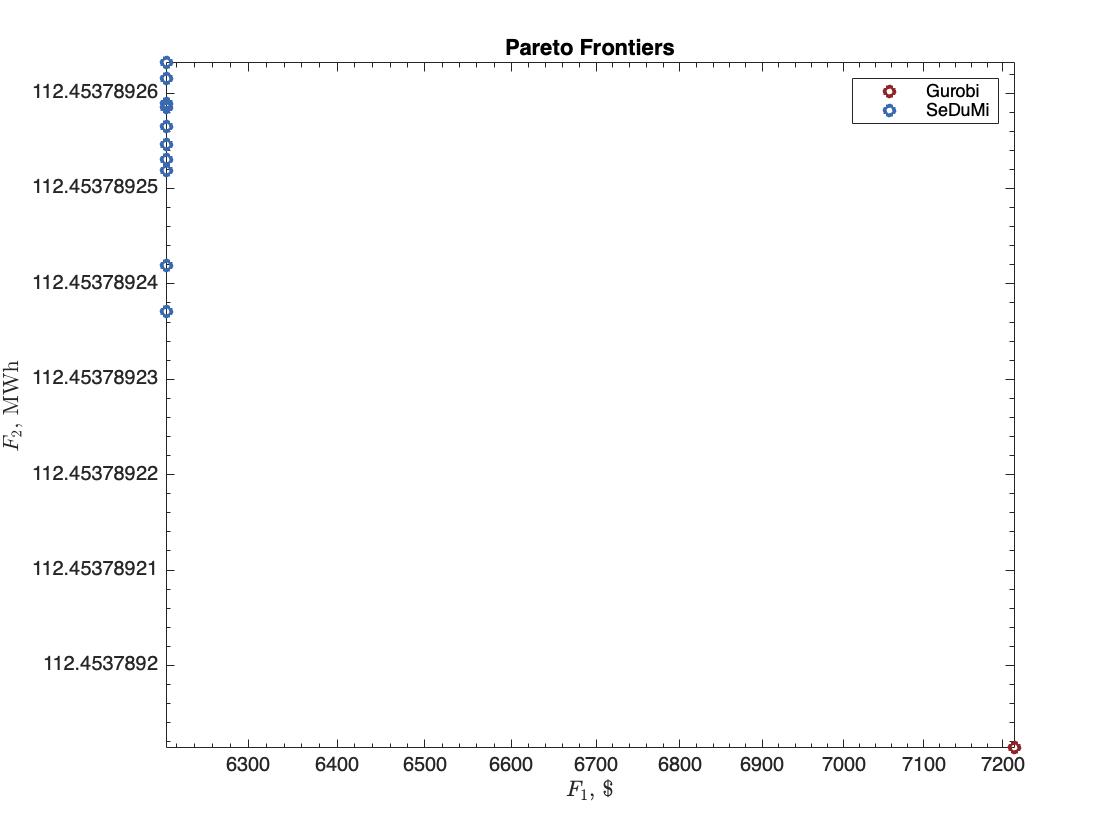

% Pareto front
figure();
loglog(cost_gurobi(:, 1), cost_gurobi(:, 2),'o', 'MarkerSize', 5, 'Color', gurobi_color, 'LineWidth', 2); hold on
loglog(cost_sedumi(:, 1), cost_sedumi(:, 2), 'o', 'MarkerSize', 5, 'Color', sedumi_color, 'LineWidth', 2); hold off
title('Pareto Frontiers');
legend('Gurobi', 'SeDuMi');
xlabel('$F_1$, \$', 'Interpreter','latex');
ylabel('$F_2$, MWh', 'Interpreter','latex');

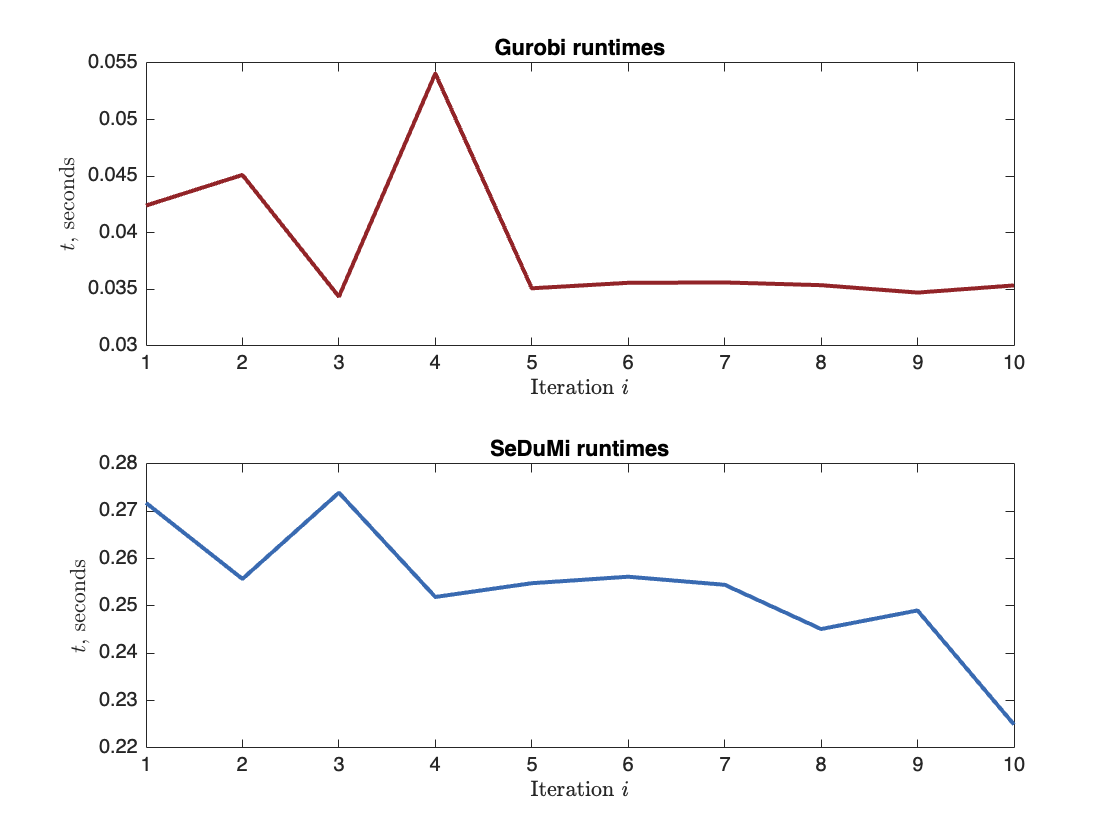

% Tiles for plot
tiledlayout(2,1);
% Move to the next plot tile
nexttile
plot(1:1:length(runtime_gurobi), runtime_gurobi, 'Color', gurobi_color, LineWidth=2);
title('Gurobi runtimes');
xlabel('Iteration $i$', 'Interpreter','latex');
ylabel('$t$, seconds', 'Interpreter','latex');
nexttile
plot(1:1:length(runtime_sedumi), runtime_sedumi, 'Color', sedumi_color, LineWidth=2);
title('SeDuMi runtimes');
xlabel('Iteration $i$', 'Interpreter','latex');
ylabel('$t$, seconds', 'Interpreter','latex');

## Gurobi: influence of penalty

% Span for uniform weights
span_pen = 0.01:0.04:0.999;
% Span for penalties
pens = [0, 25, 250];

% Placeholder variables
cost_gurobi_pen = zeros(length(span), 2);


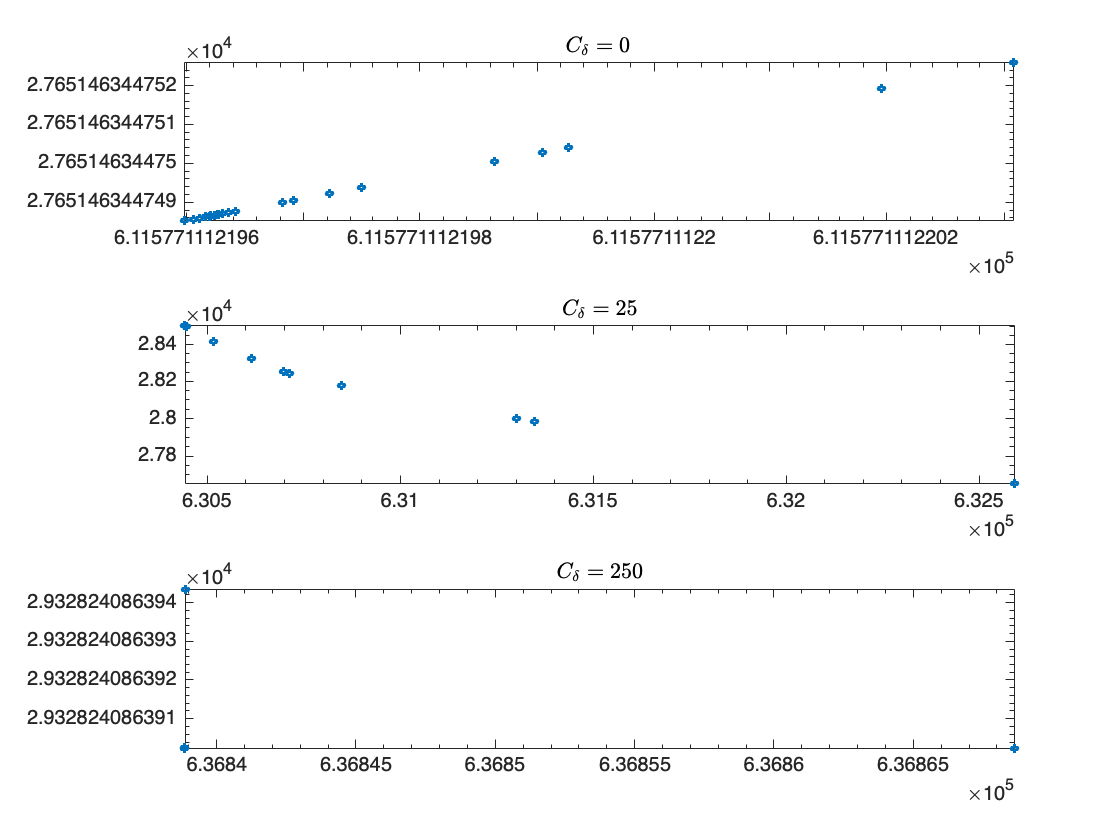

Set parameter Username
Set parameter Threads to value 1
Academic license - for non-commercial use only - expires 2025-04-13
Warning for adding variables: zero or small (< 1e-13) coefficients, ignored
Gurobi Optimizer version 11.0.1 build v11.0.1rc0 (mac64[arm] - Darwin 23.5.0 23F79)

CPU model: Apple M1
Thread count: 8 physical cores, 8 logical processors, using up to 1 threads

Optimize a model with 2436 rows, 912 columns and 4573 nonzeros
Model fingerprint: 0x0a63ccda
Model has 240 quadratic objective terms
Variable types: 336 continuous, 576 integer (576 binary)
Coefficient statistics:
  Matrix range     [1e+00, 5e+02]
  Objective range  [1e-02, 1e+04]
  QObjective range [6e-04, 1e-02]
  Bounds range     [1e+00, 1e+00]
  RHS range        [1e+00, 2e+03]
Presolve removed 1930 rows and 263 columns
Presolve time: 0.01s
Presolved: 506 rows, 649 columns, 1676 nonzeros
Presolved model has 232 quadratic objective terms
Variable types: 232 continuous, 417 integer (417 binary)
Found heuristic

% Plot graph in process
tiledlayout(length(pens), 1)

% Do a full front for every penalty
for i = 1:length(pens)
    alpha = pens(i);
    for j = 1:length(span_pen)
        w2 = span_pen(j);
        w1 = 1 - w2;
        network.c = w1 * (network.c1 + alpha * network.cpen) + w2 * network.c2;
        network.Q_biobj = network.Q * w1;
        result_gurobi = solve_gurobi(network);
        [cost_gurobi_pen(j, 1), cost_gurobi_pen(j, 2)] = objective_values(network, alpha, result_gurobi.x);
    end  
    nexttile
    loglog(cost_gurobi_pen(:, 1), cost_gurobi_pen(:, 2), 'o', 'MarkerSize', 3, 'LineWidth', 2)
    title(['$C_\delta = ', num2str(alpha), '$'], 'Interpreter', 'latex');
end

## Wind and solar generation plots (24H)

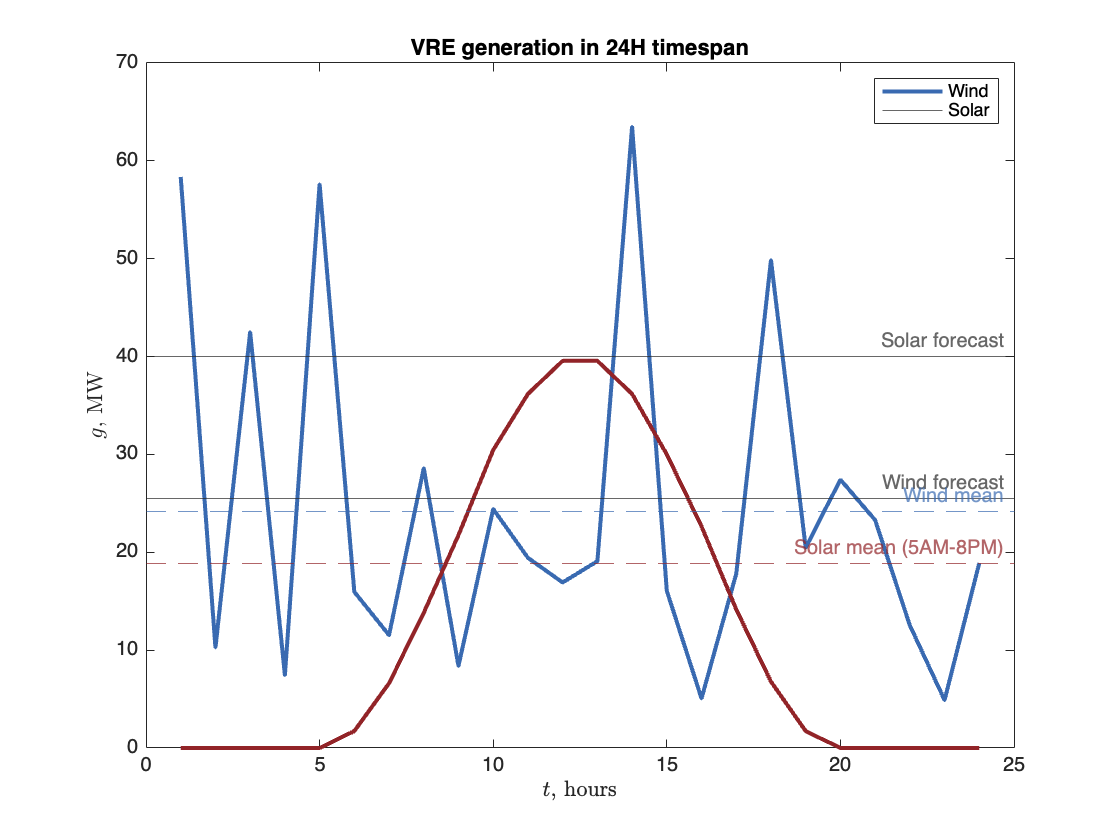

gurobi_color = [146 36 40] / 255;
sedumi_color = [57 106 177] / 255;

x = linspace(1, 24, 24);
wind_power = zeros(1, 24);
solar_power = zeros(1, 24);
for t = 1:24
    wind_power(t) = pdf(t, "wind");
    solar_power(t) = pdf(t, "solar");
end

figure()
plot(x, wind_power, Color=sedumi_color, LineWidth=2); hold on
yline(25.5,'-','Wind forecast');
yline(mean(wind_power),'--','Wind mean', Color=sedumi_color);
plot(x, solar_power, Color=gurobi_color, LineWidth=2); hold off
yline(40,'-','Solar forecast');
yline(mean(solar_power(5:20)),'--','Solar mean (5AM-8PM)', Color=gurobi_color);
title('VRE generation in 24H timespan')
legend('Wind', 'Solar');
xlabel('$t$, hours', 'Interpreter','latex');
ylabel('$g$, MW', 'Interpreter','latex');

## Example of network demand

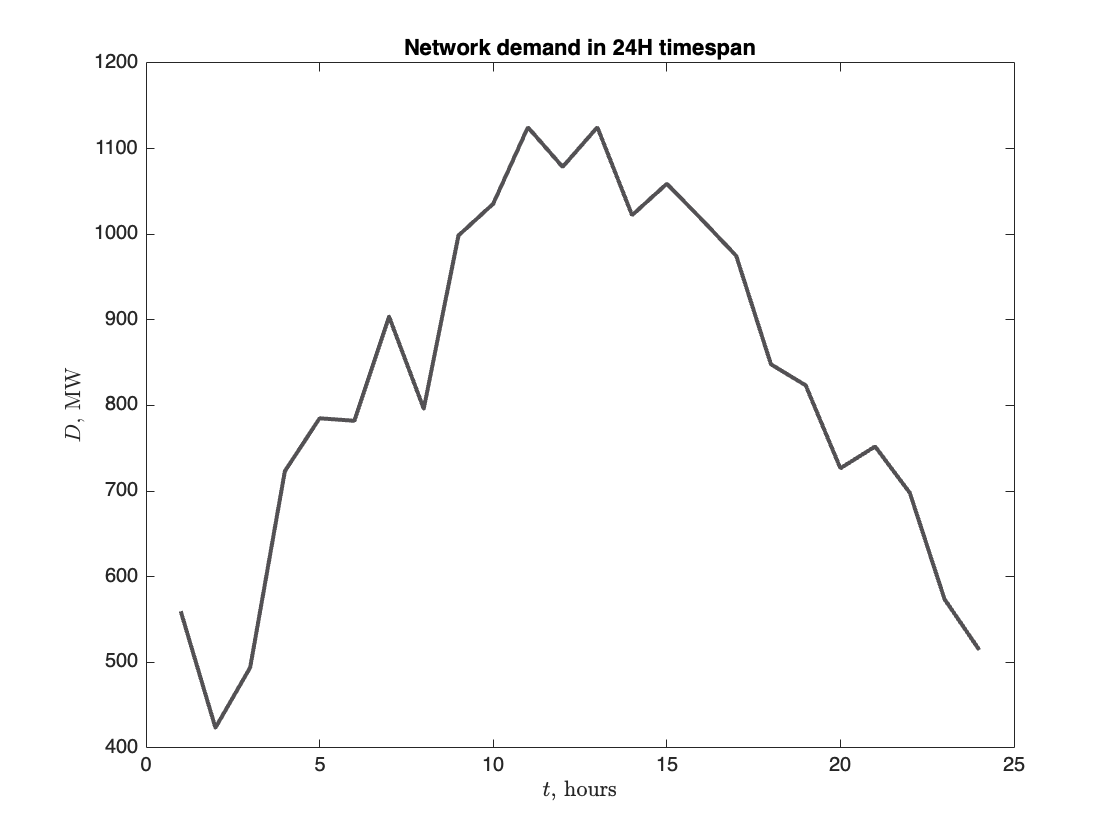

demand_color = [83 81 84]/255;

maxgen = [455, 455, 160, 55];
starting_state = [1, 1, 0, 0];
x = linspace(1, 24, 24);
demand_profile = demand(maxgen, starting_state, 24);

figure()
plot(x, demand_profile, LineWidth=2, Color=demand_color);
title('Network demand in 24H timespan')
xlabel('$t$, hours', 'Interpreter','latex');
ylabel('$D$, MW', 'Interpreter','latex');